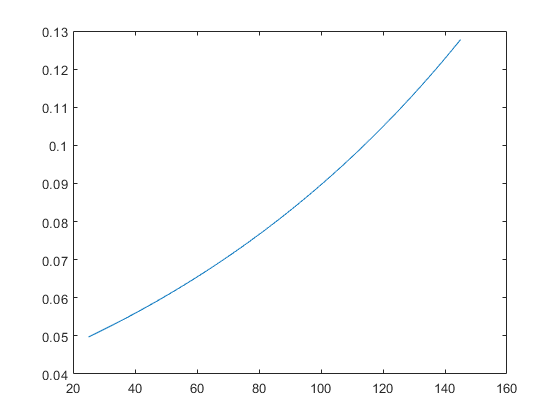

Tj = 25:145;
Ta = 20;
Rheatsink = 3.85;
Rtim = 2.5;
Rjc = 0.5;

Rtotal = 0.05*0.8167*exp(0.007865.*Tj);

Ploss = (Tj - Ta)./ (Rheatsink + Rtim + Rjc);
Isource = sqrt(Ploss./Rtotal);
figure
hold off
plot(Tj, Rtotal)

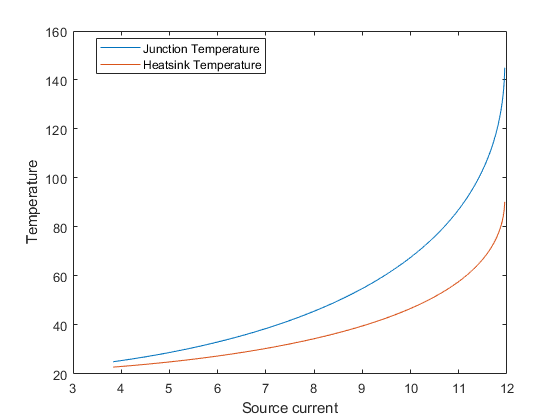

plot(Isource,Tj)
ylabel('Temperature')
xlabel('Source current')
hold on
plot(Isource,Ploss.*Rheatsink +Ta)
legend('Junction Temperature','Heatsink Temperature','Location', 'best');
hold off

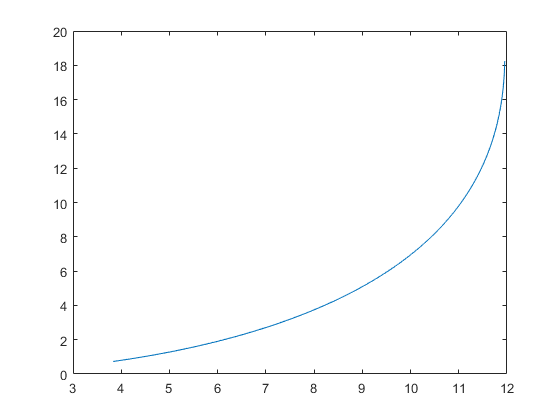

plot(Isource,Ploss)


k = 1;
for I = 0:0.1:20
    j = 1;
    for Tj = 50:0.1:145
        %P(k,j) = I^2*0.05*0.8167*exp(0.007865.*Tj);
        P(k,j) = I^2*(0.0002021.*Tj+0.03633);
        if abs(Tj - (Ta + P(k,j)*(Rtim + Rheatsink + Rjc))) > 0.4
            P(k,j) = -999;
        else
            fprintf("Temperature is %f, current is %f, power loss is %f \n",Tj,I,P(k,j))
        end
        j = j + 1;
    end
    k = k + 1;
end

Temperature is 50.000000, current is 9.700000, power loss is 4.369069 
Temperature is 50.100000, current is 9.700000, power loss is 4.370971 
Temperature is 50.200000, current is 9.700000, power loss is 4.372872 
Temperature is 50.300000, current is 9.700000, power loss is 4.374774 
Temperature is 50.200000, current is 9.800000, power loss is 4.463499 
Temperature is 50.300000, current is 9.800000, power loss is 4.465440 
Temperature is 50.400000, current is 9.800000, power loss is 4.467381 
Temperature is 50.500000, current is 9.800000, power loss is 4.469322 
Temperature is 50.600000, current is 9.800000, power loss is 4.471263 
Temperature is 50.700000, current is 9.800000, power loss is 4.473204 
Temperature is 50.800000, current is 9.800000, power loss is 4.475145 
Temperature is 50.900000, current is 9.800000, power loss is 4.477086 
Temperature is 51.000000, current is 9.800000, power loss is 4.479027 
Temperature is 50.900000, current is 9.900000, power loss is 4.568921 
Temper

%plot3(65:145,0:0.1:20,P)
%xlabel('Temperature')
%ylabel('Current')
%zlabel('Loss')